# Sensor drivers

All sensors on the AR Drone 2.0 can be read using legacy C code implementations created by the Paparazzi community. All but one sensor can be read from the AR Drone 2.0's IMU board, the only extra sensor is the battery sensor.

## The legacy IMU driver 

The IMU driver is based on the navdata C source files created by the Paparazzi community, which are still under development as of march 2016. The version used in this toolbox can therefore differ from the latest version from Paparazzi. The concepts listed below will remain the same with the process through which the IMU data goes from the IMU on the drone to Simulink. The Paparazzi implementation uses the files** "navdata.c"** and **"navdata.h".** The AR Toolbox versions of these files have been adjusted to work without external Paparazzi files and are placed in the AR Toolbox as **"IMU_Navdata.c"** and **"IMU_Navdata.h"**. The image below shows how the drone, Paparazzi code, AR Drone Toolbox code and Simulink interact.

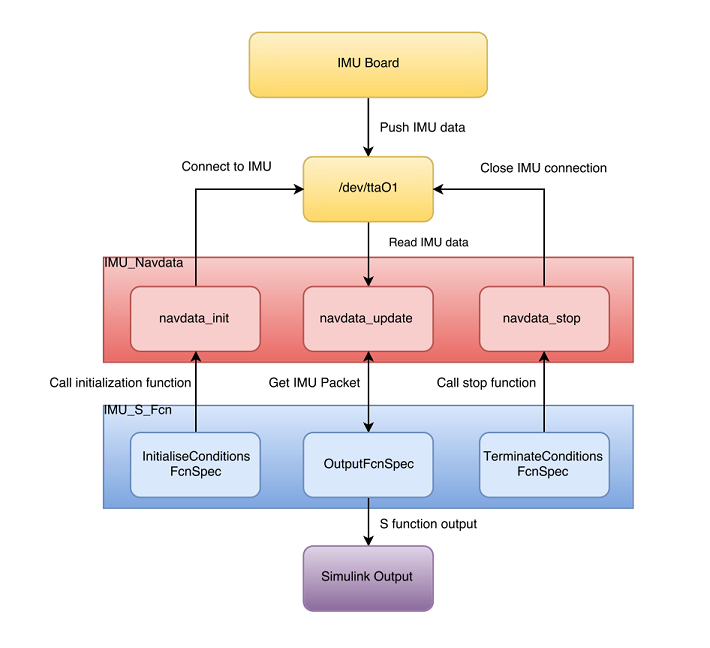

This implementation is wrapped to be used in Simulink and can be found in the [AR Drone 2 Sensors library](matlab:AR_Drone_Sensors) as:

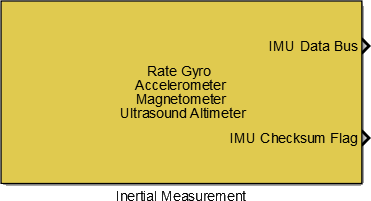

## The IMU packet data structure

The IMU outputs data in a specific format. In order to use this data format in the C code driver it is defined as the IMU_Packet struct in IMU_Navdata.h. This same data struct forms the output of the Simulink block and as such a Simulink bus object is created which uses IMU_Navdata.h as the header file to define the signals by name and type.

 IMU_Packets contains the following fields:

- taille                            unsigned int 16        Size of the IMU Packet

- nu_trame                    unsigned int 16        IMU Packet identifier number

- ax,ay,az                      signed int 16            Raw accelerometer data (x, y, z direction)

- vx,vy,vz                       signed int 16            Raw gyroscope data (x, y, z direction)

- temp_acc                    unsigned int 16        Accelerometer temperature

- temp_gyro                   unsigned int 16        Gyroscope temperature

- ultrasound                   unsigned int 16        Raw ultrasound data

Unused / unknown ultrasound parameters:

- us_debut_echo            unsigned int 16

- us_fin_echo                 unsigned int 16

- us_association_echo   unsigned int 16

- us_distance_echo        unsigned int 16

- us_cuve_time               unsigned int 16 

- us_curve_value            unsigned int 16

- us_curve_ref                unsigned int 16

- nb_echo                       unsigned int 16

- sum_echo                    unsigned int 32

- gradient                        signed int 16

- flag_echo_ini                unsigned int 16

Final known IMU Packet data:

- pressure                        signed int 16         Raw barometer data

- temperature_pressure   unsigned int 16     Barometer temperature

- mx,my,mz                      signed int 16         Raw magenetometer data (x, y, z direction)

- chksum                          unsigned int 16     Checksum for validating packet integrity.

Another output is generated by the IMU block, the IMU checksum flag. When this transitions from 1 to 0 it means the corresponding packet is not accurate. **Note: **when the checksum goes from 0 to 1 again it can occur that the IMU has not yet updated with a new correct packet. To ensure that the new packet is correct the checksum of the new packet should be compared with the checksum of the packet for which the checksum flag failed. If the checksums are different the new packet is an updated and correct packet.

## Retrieving IMU data

**Initialization**

The initialization function within the driver code opens a serial connection to /dev/ttaO1 and set the UART Baud rate to 460800 bits per second and is defined as:

(int IMU_Navdata_init())

A separate thread is then created to handle reading of the IMU data. This initialization function is specified as the InitializeConditionsFcnSpec within the legacy code tool such that it is called before the program receives the 'Start' command from the Simulink PC. If the process is unsuccessful the legacy function will return a non zero value which will cause the wrapper function to print an error.

**Update**

With the thread set up the IMU data can be read at will using the update function: 

(int IMU_Navdata_update())

This function calls a sub function which reads from the IMU connection:

(void Acquire_Navdata_Bytes())

- If the received packet starts with a NAVDATA start byte the IMU data at /dev/ttaO1 is flushed.

- The checksum is calculated to verify the packet integrity.

- The barometer values are checked as they can be switched with a temperature measurement if the IMU board is interrupted. If this occurs the values are not updated.

- Check if the magnetometer has stopped updating, if a set number of samples were the same: reset the IMU board. *Note that this functionality is not by default enabled.*

- Flush the IMU buffer such that the next time update is called it will contain only the most recent measurement.

## Stop

The stop function closes the IMU file descriptor.

# Battery voltage

The battery voltage can be read in Simulink by wrapping C code provided by the Paparazzi community. It has an initialization function which opens the */dev/i2c-1 *file descriptor after which the update function reads data over I2C.

The returned values need to be converted to volt, to this end the Paparazzi code contains a scaling factor of ~0.136 which scales the output to deciVolts and is then provided as an output by the Simulink block in the [AR Drone 2.0 Sensors library](matlab:AR_Drone_Sensors) as shown: